sl = LightSim

sl =   LightSim with properties:

    col_wl_amp_spec: [302×404 double]
          spec_dark: [1×1 SpectrumClass]
          classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@LightSim'


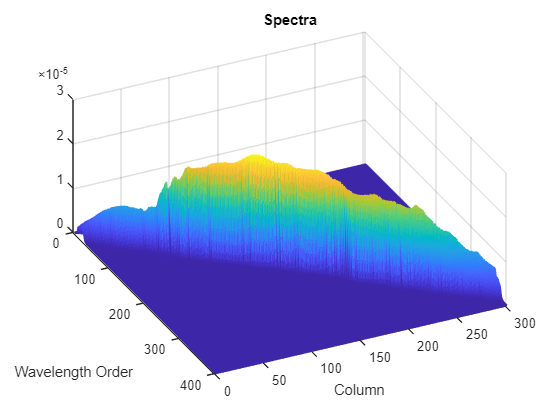


sl.check_data

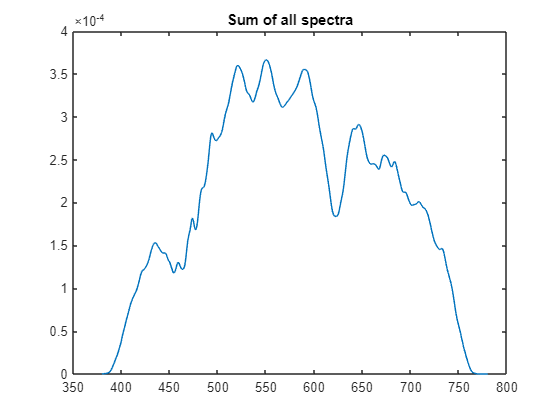

m = sl.col_wl_amp_spec(:,4:end);

s = sum(m,1);
plot(380:780,s)
title('Sum of all spectra')

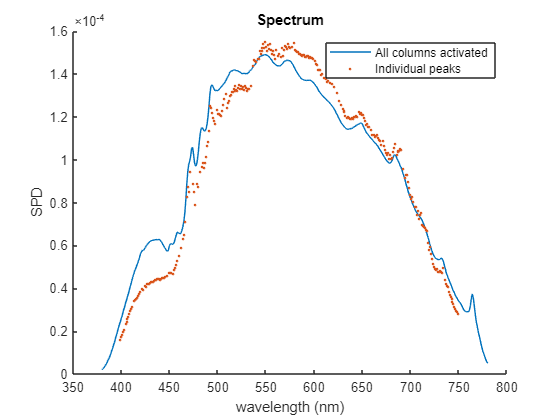

clf
hold on

load('C:\Users\wayne\Documents\GitHub\MIS_acquire\@OL490Class\ss.mat')
sall.plot

plot(sl.col_wl_amp_spec(:,2),sl.col_wl_amp_spec(:,3)*7,'.')
legend('All columns activated','Individual peaks')

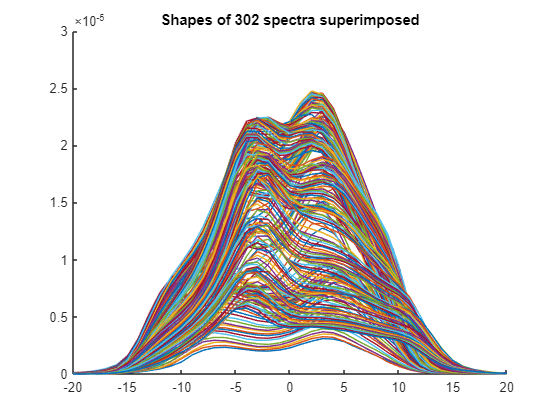

clf
hold on
for i = 1:length(sl.col_wl_amp_spec(:,1))
    x = sl.col_wl_amp_spec(i,2);
    spec = sl.col_wl_amp_spec(i,4:end);

    plot([380:780]-x,spec)
end
axis([-20 20 0 3e-5])
title('Shapes of 302 spectra superimposed')